clc;
close all;
[y1,fs] = audioread('Bach2.wav');%read wave file data and sampling freq
nbits = audioinfo('Bach2.wav');% read n bits from audio file

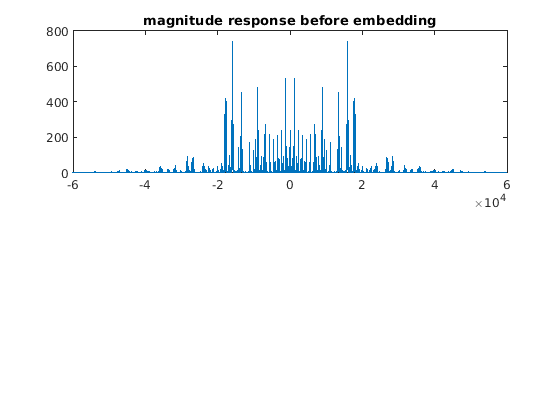

y=y1(:,1);
t=0:1/fs:10-1/fs+88/fs;%t runs over entire signal(needs to be adjusted according to your signal)
N=length(t);
X=fftshift(fft(y,N));%calculate fft of audio signal, and shift 0 component to centre
f=(-N/2:N/2-1)';
subplot(2,1,1);
plot(f,abs(X));
title('magnitude response before embedding')
axis([-60000 60000 0 800]);%adjust axis to suit your signal

y1=[1 0 0 0 1 1 1 1 1 0 0 1 1 0 0 1 0 1 0 1 0 1 1 1 0 1 0 1 0 1 0 0 1 0 0 1 1 1 0 1 0 1 0 0 1 0 1 1 0 0 ];%signal to be embeded
frame=50;         %total no of bits in embedding signal
d=10;             %no. of samples used to embedd each bit
p=500;            %(frame*d)totl no. of samples used for embedding 5khz to 5.5khz
q=N/2+1; %point of zero frequency
X4=abs(X);
X5=angle(X);
Y=X4;
X1=X4((q-5000-(p)):(q-5001)); %selecting portion for embedding
X2=X4((q+5001):(q+5001+(p-1)));
a=0.1;
x1=vec2mat(X1,d);
x2=vec2mat(X2,d);

for k=1:frame                %embedding algorithm
   avg=0;
   for l=1:d %find avg of all samples
       avg=avg+x1(k,l); 
   end
   avg=avg/d;
   if(y1(k)==0) % bit it '0'
       for l=1:d
           x1(k,l)=avg;
       end
   else
       for l=1:d/2
           x1(k,l)=a*avg;
       end
       for l=d/2+1:d
           x1(k,l)=(2-a)*avg;
       end
   end
end

x1=x1';
X3=x1(:);%converting matrix to row vector
X3=X3';
z1=((q-5000-(p)):(q-5001));
z2=((q+5001):(q+5001+(p-1)));
Y(z1)=X3;%embedding watermark in this portion
Y(z2)=fliplr(X3); % for symmetry

Y1=Y.*exp(1i*X5);% adding phase information back

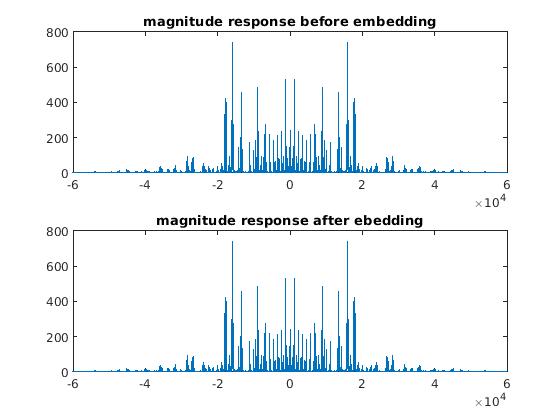

subplot(2,1,2);
plot(f,abs(Y1));
axis([6000 6500 0 800])
title('magnitude response after ebedding')
axis([-60000 60000 0 800])

C=real(ifft(ifftshift(Y1)));
audiowrite('embeded_signal.wav', C, fs);